## **Rumore Sale e Pepe**

Pixel a 0 (pepe) e pixel a 255 (sale) aggiunti come rumore ad un immagine.

Ad esempio se vogliamo introdurre il 5 percento di rumore sale e pepe, possiamo usare questo metodo con funzioni di libreria:

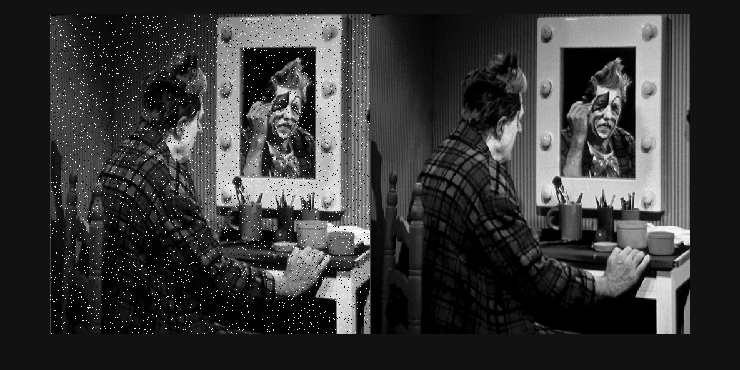

I = imread("imgs/clown.png");

% definiamo la percentuale di rumore
rumore = 0.05;

% Aggiungiamo il rumore all'immagine
img_noise = imnoise(I,"salt & pepper",rumore);
imshowpair(img_noise,I,"montage");

oppure operiamo in maniera "manuale"

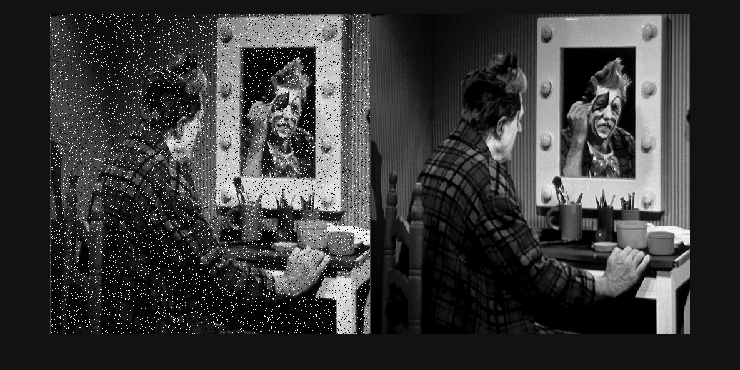

n = round(5/100 * 512 * 512); % Numero di pixel da modificare
p = randperm(512*512,2 * n); % restituisce una permutazione di lunghezza n
I2 = I;
I2(p(1:n)) = 0;
I2(p(n:2*n)) = 255;
imshowpair(I2,I,"montage");

### **Il Filtro Mediano**

È un filtro non-lineare e invece di effettuare una media pesata sceglie il valore mediano all'interno di una finestra nxn (default 3x3). **Ottino per rimuovere rumore sale e pepe.**

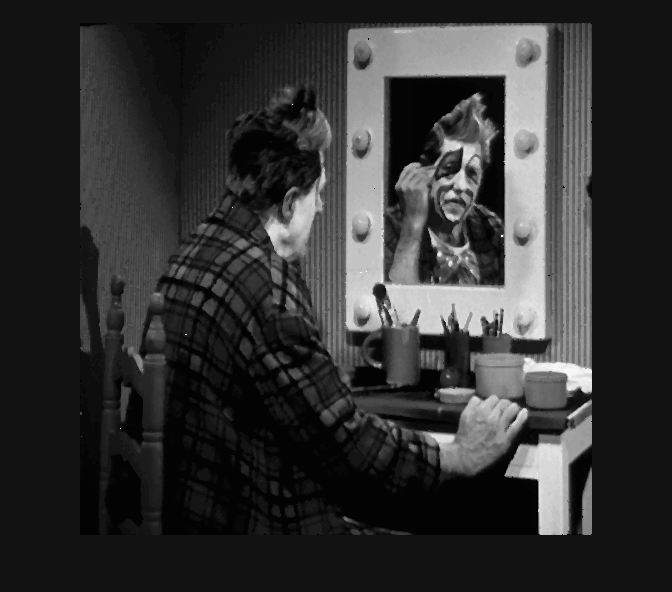

denoisedImage = medfilt2(I2); 
figure; imshow(denoisedImage)

Il filtro mediano modifica tutta l'immagine, ma possiamo ridurre le modifiche ai pixel corretti dal filtro e non tutta l'immagine. 

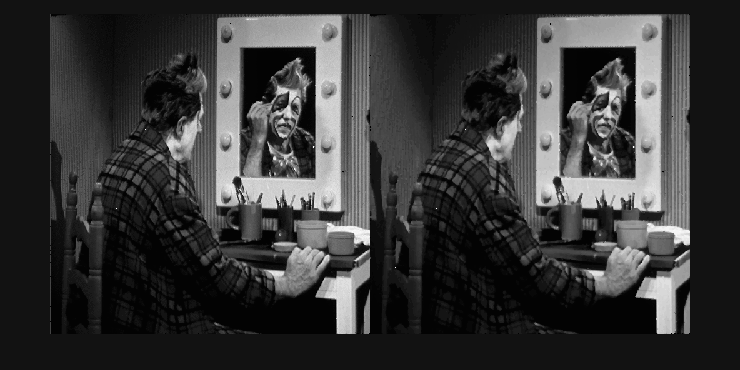

k = find(I2 == 0 | I2 == 255); % machera sui punti sale e pepe
I2(k) = denoisedImage(k); % i pixel sulla maschera vengono cambiati
imshowpair(I2,denoisedImage,"montage");

Possiamo creare una funzione personalizzata

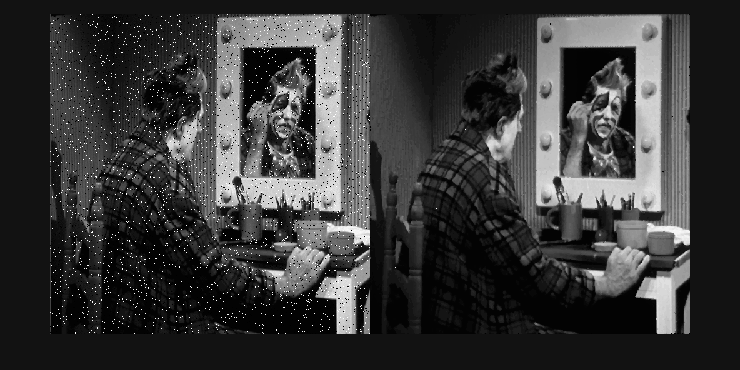

% per kernel 3x3
function output = my_median(img)
% Ottieni dimensione dell'immagine e del kernel
[h,w] = size(img);

img_padded = padarray(img, [1, 1], 'replicate');

% Inizializza la matrice output
output = zeros(h,w,"single");

% Itera sui pixel dell'immagine
for i = 2 : h - 1
    for j = 2 : w - 1

        pixels = img_padded(i - 1 : i + 1, j - 1: j - 1);
        pixels = reshape(pixels,1,[]);
        sorted_pixels = sort(pixels);
        median_value = sorted_pixels(ceil(length(sorted_pixels) / 2));
        output(i, j) = median_value;
    end
end

end

rumore = 0.05;
img_noise = imnoise(I,"salt & pepper",rumore);
denoiseImg2 = my_median(img_noise);
imshowpair(img_noise,denoisedImage,"montage")